theta = zeros(1,2);
theta(1) = 0.6155;
%theta(1) = pi/4;
theta(2) = pi/6;
% rng(2,'twister')
% rnd = rand(1,13);
% theta = pi*rnd;
% phi = zeros(1,26);
% for i = 2:2:20
%     phi(i) = pi/2;
% end
% Io = 0.1;
% F = 0.1;
% th = 0.5; %#ok<NASGU> 


%%%%%%%%%%%%%%%%
%%%% Train %%%%%
%%%%%%%%%%%%%%%%

k = 2;
N = 100;
dt = 0.1; %ms
D = 1/dt;
pw = 25;  %ms
res_t = 10;  %ms
detector_int = 1;  %ms
pmax = 0.06; %mW
poffset = 0.0; %mW
%inp = 1;
inp =randi([1,2],1,N);
L = N*(pw+res_t)*D;
inpv = sqrt(poffset)*ones(L, 1);
for i = 1:N
    inpv(round((i-1)*(pw+res_t)*D)+1:round((i-1)*(pw+res_t)*D+pw*D)) = sqrt(pmax*inp(i)+poffset);
end
% inp = [1;1;0;0;1;1];
% N = 6;
y = arr_XOR(round((inp-1)),k);



temp = zeros(2,1);
out_M = zeros(L,2);
hvec = 0.8;
hmatrix = zeros(L,1);
Pmatrix = zeros(L,1);



for i = 1:L
    [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
    out_M(i,1:2) = (abs(temp(1:2))).^2;
    hvec = hnvec;
    hmatrix(i) = hvec;
    Pmatrix(i) = P;
    %disp(i);
end

%out_M(:,7) = inp(2:N);

out_Mi = zeros(L*dt/(detector_int),2);
for i = 1:L*dt/(detector_int)
    for j = 1:2
        out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
    end
end
out_Mt = out_Mi.';
out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
out_Mo = out_Mre.';
out_Mo = out_Mo(k+1:N,1:pw*2/detector_int)/pmax;

kc = 0.01;
%w = regress(y,out_Mo);
w = ridge(y,out_Mo,kc,0);

w(1) + out_Mo*w(2:end)

ans =     0.5016
    0.3395
    0.5898
    0.5476
    0.7215
    0.4745
    0.5824
    0.5475
    0.7219
    0.5641


yo = w(1) + out_Mo*w(2:end);
yth = zeros(N-k,1);
th = 0.5;
for i=1:N-k
    if yo(i)>th
        yth(i) = 1;
    end
    if y(i)~=yth(i)
        disp(i);
    end
end

     6

    10

    11

    12

    16

    18

    19

    20

    21

    22

    23

    24

    28

    29

    32

    34

    35

    43

    45

    47

    52

    55

    56

    57

    60

    61

    68

    70

    71

    73

    77

    78

    79

    82

    84

    86

    87

    88

    89

    91

    93

    94

    97



err = rms(y-yo)

err = 0.4772

err_th = rms(y-yth)

err_th = 0.6624

%%%%%%%%%%%%%%%
%%% Delay %%%%%
%%%%%%%%%%%%%%%

M = 10;
delay_err_train_vec = zeros(M,1);
delay_err_test_vec = zeros(M,1);
dt = 0.1; %ms
D = 1/dt;
pw = 25;  %ms
res_t = 10;  %ms
detector_int = 1;  %ms
pmax = 0.06; %mW
poffset = 0.0; %mW

for k=1:M
    N = 500;
    %inp = 1;
    inp =randi([1,2],1,N);
    L = N*(pw+res_t)*D;
    inpv = sqrt(poffset)*ones(L, 1);
    for i = 1:N
        inpv(round((i-1)*(pw+res_t)*D)+1:round((i-1)*(pw+res_t)*D+pw*D)) = sqrt(pmax*inp(i)+poffset);
    end
    % inp = [1;1;0;0;1;1];
    % N = 6;
    y = arr_XOR(round((inp-1)),k);
    
    temp = zeros(2,1);
    out_M = zeros(L,2);
    hvec = 0.8;
    hmatrix = zeros(L,1);
    Pmatrix = zeros(L,1);



    for i = 1:L
        [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
        out_M(i,1:2) = (abs(temp(1:2))).^2;
        hvec = hnvec;
        hmatrix(i) = hvec;
        Pmatrix(i) = P;
        %disp(i);
    end
   
   
    out_Mi = zeros(L*dt/(detector_int),2);
    for i = 1:L*dt/(detector_int)
        for j = 1:2
            out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
        end
    end
    out_Mt = out_Mi.';
    out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
    out_Mo = out_Mre.';
    out_Mo = out_Mo(k+1:N,1:pw*2/detector_int)/pmax;
    
    kc = 0.01;
    %w = regress(y,out_Mo);
    w = ridge(y,out_Mo,kc,0);
    
    yo = w(1) + out_Mo*w(2:end);
    yth = zeros(N-k,1);
    th = 0.5;
    ct = 0;
    for i=1:N-k
        if yo(i)>th
            yth(i) = 1;
        end
        if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
        end
    end
    delay_err_train_vec(k) = ct*100/(N-k);
    
    MN = 10;
    temp_err = zeros(MN,1);
    for ji = 1:MN
        N = 20;
      
        %inp = 1;
        inp =randi([1,2],1,N);
        L = N*(pw+res_t)*D;
        inpv = sqrt(poffset)*ones(L, 1);
        for i = 1:N
            inpv(round((i-1)*(pw+res_t)*D)+1:round((i-1)*(pw+res_t)*D+pw*D)) = sqrt(pmax*inp(i)+poffset);
        end
        % inp = [1;1;0;0;1;1];
        % N = 6;
        y = arr_XOR(round((inp-1)),k);
    
        temp = zeros(2,1);
        out_M = zeros(L,2);
        hvec = 0.8;
        hmatrix = zeros(L,1);
        Pmatrix = zeros(L,1);



        for i = 1:L
            [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
            out_M(i,1:2) = (abs(temp(1:2))).^2;
            hvec = hnvec;
            hmatrix(i) = hvec;
            Pmatrix(i) = P;
            %disp(i);
        end
   
   
        out_Mi = zeros(L*dt/(detector_int),2);
        for i = 1:L*dt/(detector_int)
            for j = 1:2
                out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
            end
        end
        out_Mt = out_Mi.';
        out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
        out_Mo = out_Mre.';
        out_Mo = out_Mo(k+1:N,1:pw*2/detector_int)/pmax;
    
    
        yo = w(1) + out_Mo*w(2:end);
        yth = zeros(N-k,1);
        th = 0.5;
        ct = 0;
        for i=1:N-k
            if yo(i)>th
                yth(i) = 1;
            end
            if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
            end
        end
    temp_err(ji) = ct*100/(N-k);
    end
    delay_err_test_vec(k) = mean(temp_err(:));
end

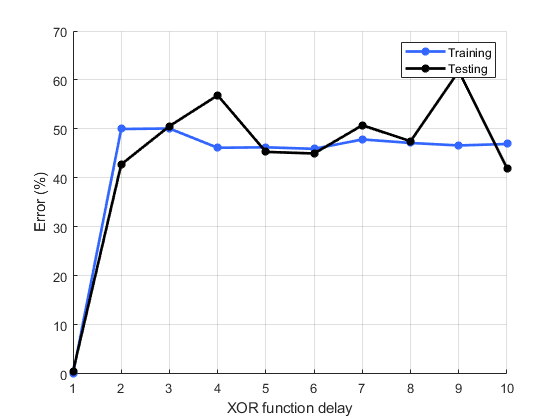

figure; hold on;
plot(delay_err_train_vec,'LineWidth',2,'Marker','*',"Color",[0.2 0.4 1])
plot(delay_err_test_vec,'LineWidth',2,'Marker','*',"Color",'k')
grid on;
ylabel('Error (%)')
xlabel('XOR function delay')
legend('Training','Testing')

%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Restore time %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%

M = 26;
restore_err_train_vec = zeros(M,1);
restore_err_test_vec = zeros(M,1);
dt = 0.1; %ms
D = 1/dt;
pw = 25;  %ms
%res_t = 20;  %ms
res_t = 0:1:25;
detector_int = 1;  %ms
pmax = 0.06; %mW
poffset = 0.0; %mW
d = 1;

for k=1:M
    N = 100;
    %inp = 1;
    inp =randi([1,2],1,N);
    L = N*(pw+res_t(k))*D;
    inpv = sqrt(poffset)*ones(L, 1);
    for i = 1:N
        inpv(round((i-1)*(pw+res_t(k))*D)+1:round((i-1)*(pw+res_t(k))*D+pw*D)) = sqrt(pmax*inp(i)+poffset);
    end
    % inp = [1;1;0;0;1;1];
    % N = 6;
    y = arr_XOR(round((inp-1)),d);
    
    temp = zeros(2,1);
    out_M = zeros(L,2);
    hvec = 0.8;
    hmatrix = zeros(L,1);
    Pmatrix = zeros(L,1);



    for i = 1:L
        [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
        out_M(i,1:2) = (abs(temp(1:2))).^2;
        hvec = hnvec;
        hmatrix(i) = hvec;
        Pmatrix(i) = P;
        %disp(i);
    end
   
   
    out_Mi = zeros(L*dt/(detector_int),2);
    for i = 1:L*dt/(detector_int)
        for j = 1:2
            out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
        end
    end
    out_Mt = out_Mi.';
    out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
    out_Mo = out_Mre.';
    out_Mo = out_Mo(d+1:N,1:pw*2/detector_int)/pmax;
    
    kc = 0.01;
    %w = regress(y,out_Mo);
    w = ridge(y,out_Mo,kc,0);
    
    yo = w(1) + out_Mo*w(2:end);
    yth = zeros(N-d,1);
    th = 0.5;
    ct = 0;
    for i=1:N-d
        if yo(i)>th
            yth(i) = 1;
        end
        if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
        end
    end
    restore_err_train_vec(k) = ct*100/(N-d);
    
    MN = 10;
    temp_err = zeros(MN,1);
    for ji = 1:MN
        N = 20;
      
        %inp = 1;
        inp =randi([1,2],1,N);
        L = N*(pw+res_t(k))*D;
        inpv = sqrt(poffset)*ones(L, 1);
        for i = 1:N
            inpv(round((i-1)*(pw+res_t(k))*D)+1:round((i-1)*(pw+res_t(k))*D+pw*D)) = sqrt(pmax*inp(i)+poffset);
        end
        % inp = [1;1;0;0;1;1];
        % N = 6;
        y = arr_XOR(round((inp-1)),d);
    
        temp = zeros(2,1);
        out_M = zeros(L,2);
        hvec = 0.8;
        hmatrix = zeros(L,1);
        Pmatrix = zeros(L,1);



        for i = 1:L
            [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
            out_M(i,1:2) = (abs(temp(1:2))).^2;
            hvec = hnvec;
            hmatrix(i) = hvec;
            Pmatrix(i) = P;
            %disp(i);
        end
   
   
        out_Mi = zeros(L*dt/(detector_int),2);
        for i = 1:L*dt/(detector_int)
            for j = 1:2
                out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
            end
        end
        out_Mt = out_Mi.';
        out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
        out_Mo = out_Mre.';
        out_Mo = out_Mo(d+1:N,1:pw*2/detector_int)/pmax;
    
    
        yo = w(1) + out_Mo*w(2:end);
        yth = zeros(N-d,1);
        th = 0.5;
        ct = 0;
        for i=1:N-d
            if yo(i)>th
                yth(i) = 1;
            end
            if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
            end
        end
    temp_err(ji) = ct*100/(N-d);
    end
    restore_err_test_vec(k) = mean(temp_err(:));
end

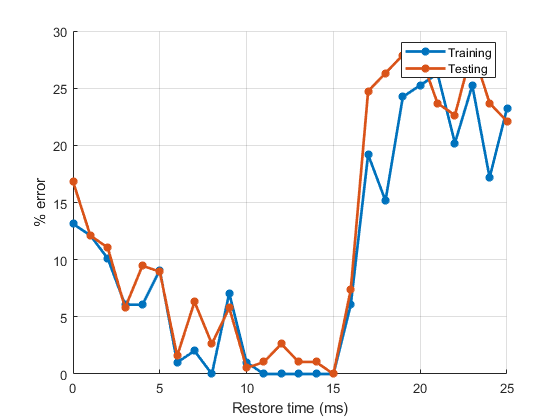

figure; hold on;
plot(res_t,restore_err_train_vec,'LineWidth',2,'Marker','*')
plot(res_t,restore_err_test_vec,'LineWidth',2,'Marker','*')
grid on;
ylabel('% error')
xlabel('Restore time (ms)')
legend('Training','Testing')

%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% Power %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%

M = 20;
power_err_train_vec = zeros(M,1);
power_err_test_vec = zeros(M,1);
dt = 0.1; %ms
D = 1/dt;
pw = 25;  %ms
res_t = 10;  %ms
detector_int = 1;  %ms
%pmax = 0.06; %mW
pmax = 0.01:0.01:0.2;
poffset = 0.0; %mW
d = 1;

for k=1:M
    N = 100;
    %inp = 1;
    inp =randi([1,2],1,N);
    L = N*(pw+res_t)*D;
    inpv = sqrt(poffset)*ones(L, 1);
    for i = 1:N
        inpv(round((i-1)*(pw+res_t)*D)+1:round((i-1)*(pw+res_t)*D+pw*D)) = sqrt(pmax(k)*inp(i)+poffset);
    end
    % inp = [1;1;0;0;1;1];
    % N = 6;
    y = arr_XOR(round((inp-1)),d);
    
    temp = zeros(2,1);
    out_M = zeros(L,2);
    hvec = 0.8;
    hmatrix = zeros(L,1);
    Pmatrix = zeros(L,1);



    for i = 1:L
        [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
        out_M(i,1:2) = (abs(temp(1:2))).^2;
        hvec = hnvec;
        hmatrix(i) = hvec;
        Pmatrix(i) = P;
        %disp(i);
    end
   
   
    out_Mi = zeros(L*dt/(detector_int),2);
    for i = 1:L*dt/(detector_int)
        for j = 1:2
            out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
        end
    end
    out_Mt = out_Mi.';
    out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
    out_Mo = out_Mre.';
    out_Mo = out_Mo(d+1:N,1:pw*2/detector_int)/pmax(k);
    
    kc = 0.01;
    %w = regress(y,out_Mo);
    w = ridge(y,out_Mo,kc,0);
    
    yo = w(1) + out_Mo*w(2:end);
    yth = zeros(N-d,1);
    th = 0.5;
    ct = 0;
    for i=1:N-d
        if yo(i)>th
            yth(i) = 1;
        end
        if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
        end
    end
    power_err_train_vec(k) = ct*100/(N-d);
    
    MN = 10;
    temp_err = zeros(MN,1);
    for ji = 1:MN
        N = 20;
      
        %inp = 1;
        inp =randi([1,2],1,N);
        L = N*(pw+res_t)*D;
        inpv = sqrt(poffset)*ones(L, 1);
        for i = 1:N
            inpv(round((i-1)*(pw+res_t)*D)+1:round((i-1)*(pw+res_t)*D+pw*D)) = sqrt(pmax(k)*inp(i)+poffset);
        end
        % inp = [1;1;0;0;1;1];
        % N = 6;
        y = arr_XOR(round((inp-1)),d);
    
        temp = zeros(2,1);
        out_M = zeros(L,2);
        hvec = 0.8;
        hmatrix = zeros(L,1);
        Pmatrix = zeros(L,1);



        for i = 1:L
            [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
            out_M(i,1:2) = (abs(temp(1:2))).^2;
            hvec = hnvec;
            hmatrix(i) = hvec;
            Pmatrix(i) = P;
            %disp(i);
        end
   
   
        out_Mi = zeros(L*dt/(detector_int),2);
        for i = 1:L*dt/(detector_int)
            for j = 1:2
                out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
            end
        end
        out_Mt = out_Mi.';
        out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
        out_Mo = out_Mre.';
        out_Mo = out_Mo(d+1:N,1:pw*2/detector_int)/pmax(k);
    
    
        yo = w(1) + out_Mo*w(2:end);
        yth = zeros(N-d,1);
        th = 0.5;
        ct = 0;
        for i=1:N-d
            if yo(i)>th
                yth(i) = 1;
            end
            if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
            end
        end
    temp_err(ji) = ct*100/(N-d);
    end
    power_err_test_vec(k) = mean(temp_err(:));
end

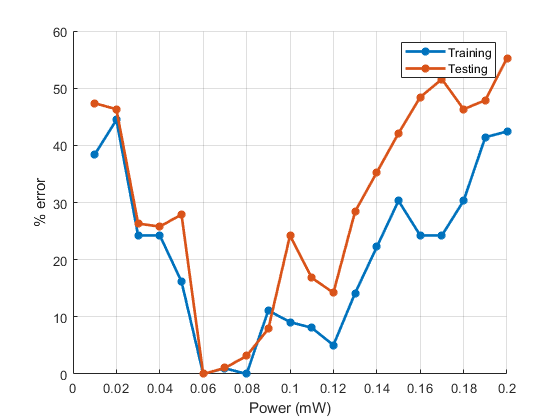

figure; hold on;
plot(pmax,power_err_train_vec,'LineWidth',2,'Marker','*')
plot(pmax,power_err_test_vec,'LineWidth',2,'Marker','*')
grid on;
ylabel('% error')
xlabel('Power (mW)')
legend('Training','Testing')

%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Pulse Width %%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%

M = 40;
pw_err_train_vec = zeros(M,1);
pw_err_test_vec = zeros(M,1);
dt = 0.1; %ms
D = 1/dt;
pw = 1:40;  %ms
res_t = 10;  %ms
detector_int = 1;  %ms
pmax = 0.06; %mW
poffset = 0.0; %mW
d = 2;

for k=1:M
    N = 100;
    %inp = 1;
    inp =randi([1,2],1,N);
    L = N*(pw(k)+res_t)*D;
    inpv = sqrt(poffset)*ones(L, 1);
    for i = 1:N
        inpv(round((i-1)*(pw(k)+res_t)*D)+1:round((i-1)*(pw(k)+res_t)*D+pw(k)*D)) = sqrt(pmax*inp(i)+poffset);
    end
    % inp = [1;1;0;0;1;1];
    % N = 6;
    y = arr_XOR(round((inp-1)),d);
    
    temp = zeros(2,1);
    out_M = zeros(L,2);
    hvec = 0.8;
    hmatrix = zeros(L,1);
    Pmatrix = zeros(L,1);



    for i = 1:L
        [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
        out_M(i,1:2) = (abs(temp(1:2))).^2;
        hvec = hnvec;
        hmatrix(i) = hvec;
        Pmatrix(i) = P;
        %disp(i);
    end
   
   
    out_Mi = zeros(L*dt/(detector_int),2);
    for i = 1:L*dt/(detector_int)
        for j = 1:2
            out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
        end
    end
    out_Mt = out_Mi.';
    out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
    out_Mo = out_Mre.';
    out_Mo = out_Mo(d+1:N,1:pw(k)*2/detector_int)/pmax;
    
    kc = 0.01;
    %w = regress(y,out_Mo);
    w = ridge(y,out_Mo,kc,0);
    
    yo = w(1) + out_Mo*w(2:end);
    yth = zeros(N-d,1);
    th = 0.5;
    ct = 0;
    for i=1:N-d
        if yo(i)>th
            yth(i) = 1;
        end
        if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
        end
    end
    pw_err_train_vec(k) = ct*100/(N-d);
    
    MN = 10;
    temp_err = zeros(MN,1);
    for ji = 1:MN
        N = 20;
      
        %inp = 1;
        inp =randi([1,2],1,N);
        L = N*(pw(k)+res_t)*D;
        inpv = sqrt(poffset)*ones(L, 1);
        for i = 1:N
            inpv(round((i-1)*(pw(k)+res_t)*D)+1:round((i-1)*(pw(k)+res_t)*D+pw(k)*D)) = sqrt(pmax*inp(i)+poffset);
        end
        % inp = [1;1;0;0;1;1];
        % N = 6;
        y = arr_XOR(round((inp-1)),d);
    
        temp = zeros(2,1);
        out_M = zeros(L,2);
        hvec = 0.8;
        hmatrix = zeros(L,1);
        Pmatrix = zeros(L,1);



        for i = 1:L
            [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
            out_M(i,1:2) = (abs(temp(1:2))).^2;
            hvec = hnvec;
            hmatrix(i) = hvec;
            Pmatrix(i) = P;
            %disp(i);
        end
   
   
        out_Mi = zeros(L*dt/(detector_int),2);
        for i = 1:L*dt/(detector_int)
            for j = 1:2
                out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
            end
        end
        out_Mt = out_Mi.';
        out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
        out_Mo = out_Mre.';
        out_Mo = out_Mo(d+1:N,1:pw(k)*2/detector_int)/pmax;
    
    
        yo = w(1) + out_Mo*w(2:end);
        yth = zeros(N-d,1);
        th = 0.5;
        ct = 0;
        for i=1:N-d
            if yo(i)>th
                yth(i) = 1;
            end
            if y(i)~=yth(i)
            %disp(i);
            ct = ct + 1;
            end
        end
    temp_err(ji) = ct*100/(N-d);
    end
    pw_err_test_vec(k) = mean(temp_err(:));
end

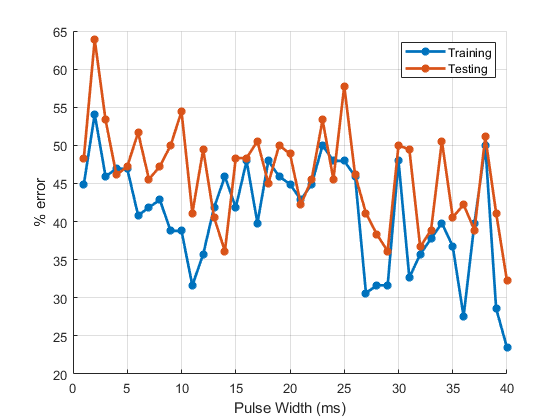

figure; hold on;
plot(pw,pw_err_train_vec,'LineWidth',2,'Marker','*')
plot(pw,pw_err_test_vec,'LineWidth',2,'Marker','*')
grid on;
ylabel('% error')
xlabel('Pulse Width (ms)')
legend('Training','Testing')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Restore time x Power %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Mp = 20;
Mr = 26;
pxet_err_train_mat = zeros(Mp,Mr);
pxet_err_test_mat = zeros(Mp,Mr);
dt = 0.1; %ms
D = 1/dt;
pw = 25;  %ms
%res_t = 10;  %ms
res_t = 0:1:25;
detector_int = 1;  %ms
%pmax = 0.06; %mW
pmax = 0.01:0.01:0.2;
poffset = 0.0; %mW
d = 1;

for kr = 1:Mr
    for kp= 1:Mp
        N = 500;
        %inp = 1;
        inp =randi([1,2],1,N);
        L = N*(pw+res_t(kr))*D;
        inpv = sqrt(poffset)*ones(L, 1);
        for i = 1:N
            inpv(round((i-1)*(pw+res_t(kr))*D)+1:round((i-1)*(pw+res_t(kr))*D+pw*D)) = sqrt(pmax(kp)*inp(i)+poffset);
        end
        % inp = [1;1;0;0;1;1];
        % N = 6;
        y = arr_XOR(round((inp-1)),d);
    
        temp = zeros(2,1);
        out_M = zeros(L,2);
        hvec = 0.8;
        hmatrix = zeros(L,1);
        Pmatrix = zeros(L,1);



        for i = 1:L
            [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
            out_M(i,1:2) = (abs(temp(1:2))).^2;
            hvec = hnvec;
            hmatrix(i) = hvec;
            Pmatrix(i) = P;
            %disp(i);
        end
   
   
        out_Mi = zeros(L*dt/(detector_int),2);
        for i = 1:L*dt/(detector_int)
            for j = 1:2
                out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
            end
        end
        out_Mt = out_Mi.';
        out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
        out_Mo = out_Mre.';
        out_Mo = out_Mo(d+1:N,1:pw*2/detector_int)/pmax(kp);
    
        kc = 0.01;
        %w = regress(y,out_Mo);
        w = ridge(y,out_Mo,kc,0);
    
        yo = w(1) + out_Mo*w(2:end);
        yth = zeros(N-d,1);
        th = 0.5;
        ct = 0;
        for i=1:N-d
            if yo(i)>th
                yth(i) = 1;
            end
            if y(i)~=yth(i)
                %disp(i);
                ct = ct + 1;
            end
        end
        pxet_err_train_mat(kp,kr) = ct*100/(N-d);
    
        MN = 10;
        temp_err = zeros(MN,1);
        for ji = 1:MN
            N = 20;
      
            %inp = 1;
            inp =randi([1,2],1,N);
            L = N*(pw+res_t(kr))*D;
            inpv = sqrt(poffset)*ones(L, 1);
            for i = 1:N
                inpv(round((i-1)*(pw+res_t(kr))*D)+1:round((i-1)*(pw+res_t(kr))*D+pw*D)) = sqrt(pmax(kp)*inp(i)+poffset);
            end
            % inp = [1;1;0;0;1;1];
            % N = 6;
            y = arr_XOR(round((inp-1)),d);
    
            temp = zeros(2,1);
            out_M = zeros(L,2);
            hvec = 0.8;
            hmatrix = zeros(L,1);
            Pmatrix = zeros(L,1);



            for i = 1:L
                [temp(1), temp(2),hnvec,P] = RC_1coup(inpv(i),theta,hvec,dt);
                out_M(i,1:2) = (abs(temp(1:2))).^2;
                hvec = hnvec;
                hmatrix(i) = hvec;
                Pmatrix(i) = P;
                %disp(i);
            end
   
   
            out_Mi = zeros(L*dt/(detector_int),2);
            for i = 1:L*dt/(detector_int)
                for j = 1:2
                    out_Mi(i,j) = mean(out_M((i-1)*detector_int/dt+1:i*detector_int/dt,j));
                end
            end
            out_Mt = out_Mi.';
            out_Mre = reshape(out_Mt,[2*L*dt/(detector_int*N),N]);
            out_Mo = out_Mre.';
            out_Mo = out_Mo(d+1:N,1:pw*2/detector_int)/pmax(kp);
    
    
            yo = w(1) + out_Mo*w(2:end);
            yth = zeros(N-d,1);
            th = 0.5;
            ct = 0;
            for i=1:N-d
                if yo(i)>th
                    yth(i) = 1;
                end
                if y(i)~=yth(i)
                %disp(i);
                ct = ct + 1;
                end
            end
        temp_err(ji) = ct*100/(N-d);
        end
        pxet_err_test_mat(kp,kr) = mean(temp_err(:));

    end
end
        

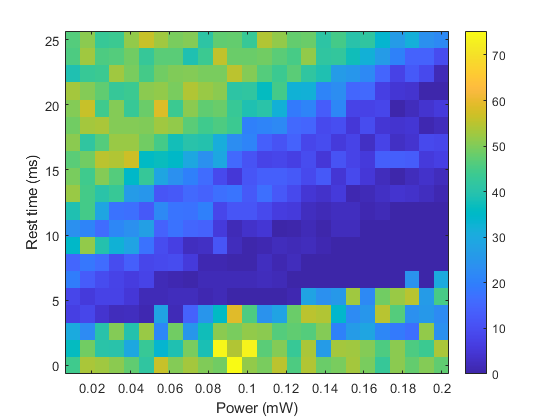

figure;
colorMap = [linspace(0,1,256)', zeros(256,2)];
imagesc(pmax,res_t,pxet_err_test_mat); colormap colormap; axis xy;colorbar;
xlabel('Power (mW)')
ylabel('Rest time (ms)')

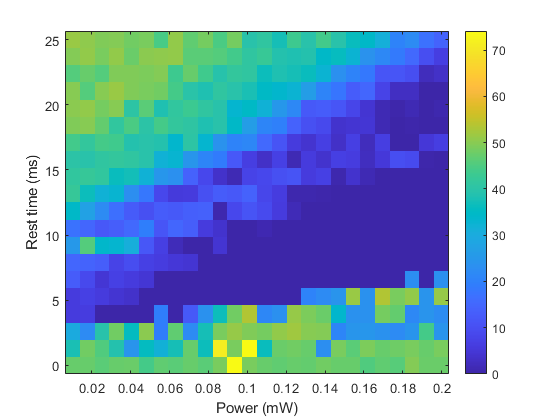


figure;
colorMap = [linspace(0,1,256)', zeros(256,2)];
imagesc(pmax,res_t,pxet_err_train_mat); colormap colormap; axis xy;colorbar;
xlabel('Power (mW)')
ylabel('Rest time (ms)')

min(pxet_err_test_mat,[],'all')

ans = 8.3333

min(pxet_err_train_mat,[],'all')

ans = 7.0281